# Sesión 8

Yimin Pan, Santi Otin

Grup 12

## 1. Repàs de la segmentació per watershed

#### Obriu la imatge 'cornea.tif' 

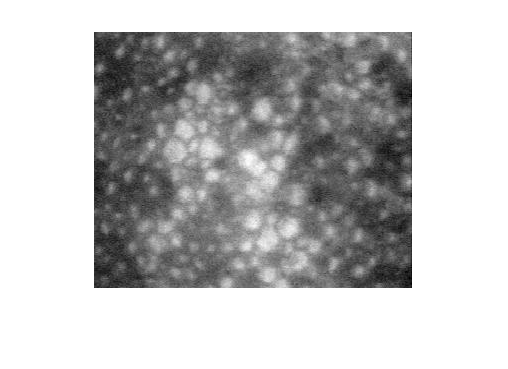

orig = imread('cornea.tif');
figure, imshow(orig)

% calculem el gradient. Ho podem fer morfològic

#### creeu un element estructurant de tipus disc, radi 1

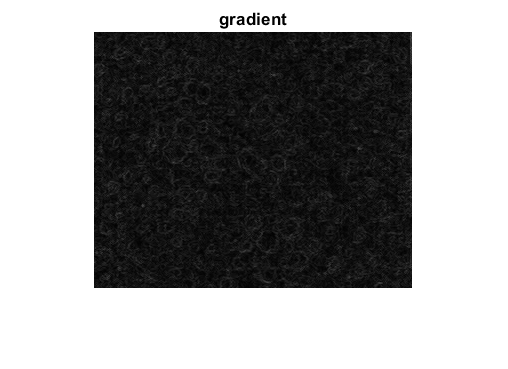

ee = strel('disk', 1);
grad=imsubtract(imdilate(orig,ee),imerode(orig,ee));
figure,imshow(grad),title('gradient')

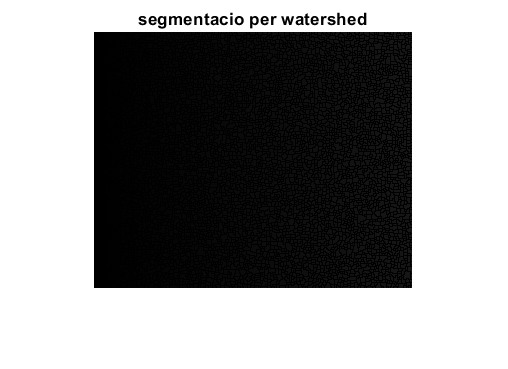

% mirem de segmentar les cèlules fent watershed sobre la imatge gradient
segm=watershed(grad);
figure,imshow(segm), title('segmentacio per watershed')

% resultat sobresegmentat. Cal treballar amb markers

## marker-controlled watershed

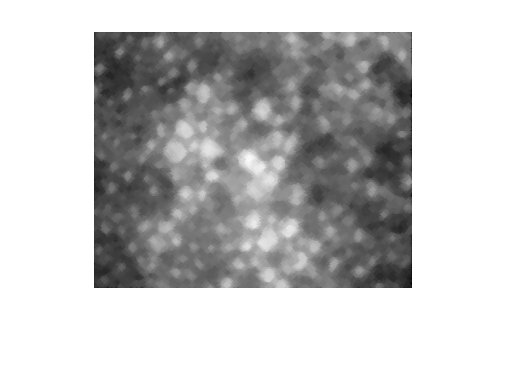

% usarem els màxims regionals com a markers de les cèlules
% la imatge és molt sorollosa. Cal filtrar abans
ee=strel('disk',2);
filt=imopen(imclose(orig,ee),ee); %filtre OC
figure,imshow(filt)

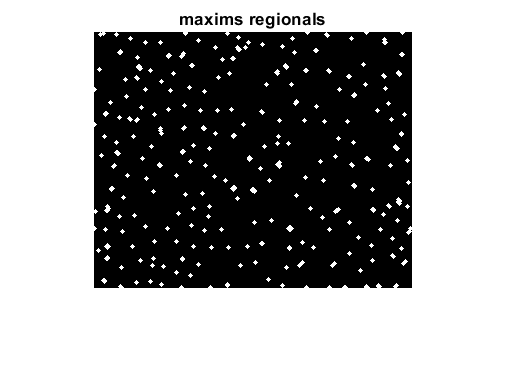

rm=imregionalmax(filt);
figure,imshow(rm),title('maxims regionals')

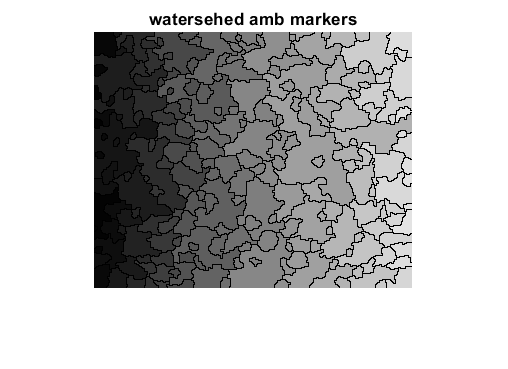

% Usem els maxims regionals com a markers pel watershed
segm=watershed(imimposemin(grad,rm));
figure,imshow(segm),title('watersehed amb markers')

#### Feu un overlay, en color, dels contorns obtinguts sobre la imatge original Us sembla correcta la segmentació? O ens em oblidat alguna cosa ? 

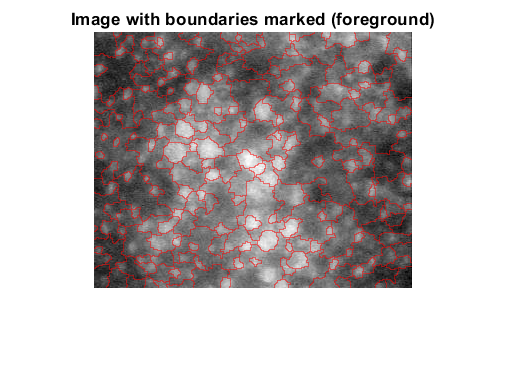

labels = imdilate(segm==0,ones(1));
C = [1, 0, 0];
imSeg = labeloverlay(orig, labels, 'Colormap', C);
figure; imshow(imSeg); title('Image with boundaries marked (foreground)');

El resultat no es correcta, el watershed separa els objectes en regions peró el marker no els aïlla bé (hauria de marcar solament els edge dels objectes).

## Cal trobar un marker pel fons

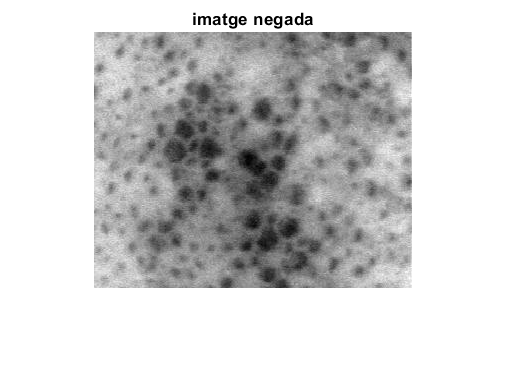

% L'obtenim fent el watershed de la imatge negada.
%Usem com a markers els mateixos maxims d'abans
Norig=imcomplement(orig);
figure,imshow(Norig),title('imatge negada')

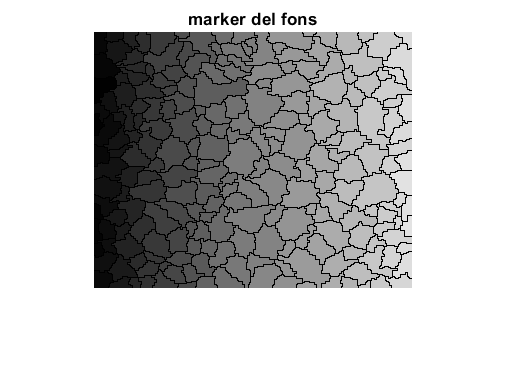

fons=watershed(imimposemin(Norig,rm));
figure,imshow(fons),title('marker del fons')

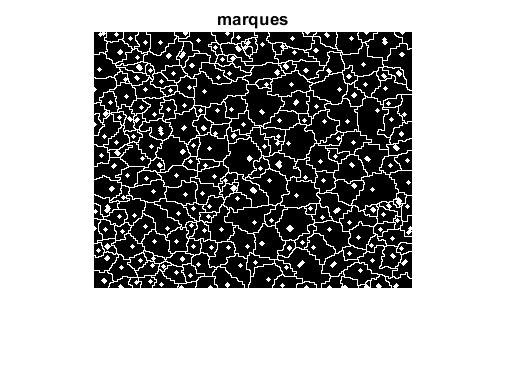

% Fem una imatge de markers a partir de les celules i del fons
markers=~fons|rm;
figure,imshow(markers),title('marques')

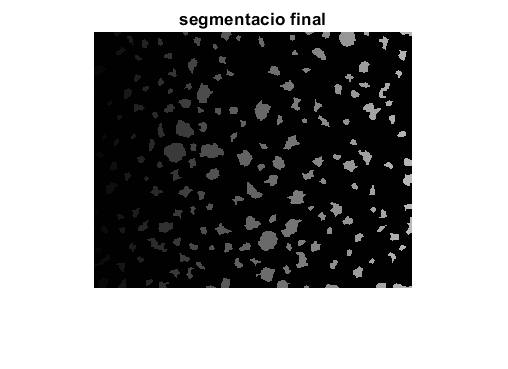

% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

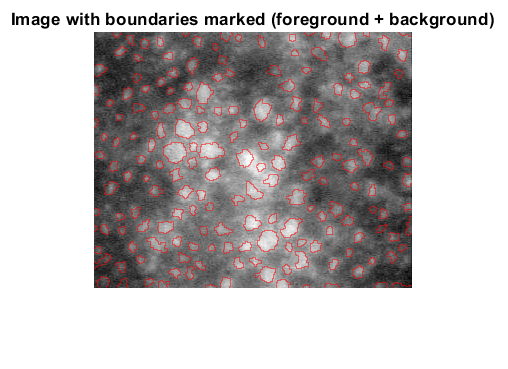

labels = imdilate(segm==0,ones(1));
C = [1, 0, 0];
imSeg = labeloverlay(orig, labels, 'Colormap', C);
figure; imshow(imSeg); title('Image with boundaries marked (foreground + background)');

## hem perdut alguna cèlula.

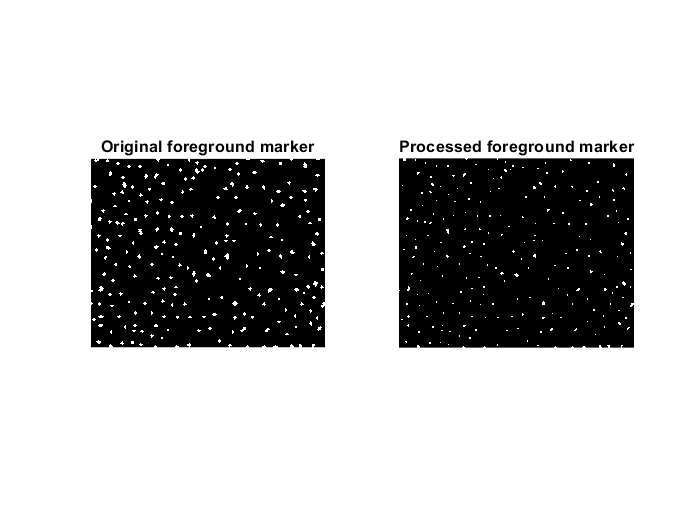

% Aixó és degut a que alguns markers de les celules es toquen amb el marker del fons (veure imatge  markers’)
se2 = strel(ones(2,2));
rm2 = imclose(rm,se2);
rm3 = imerode(rm2,se2);
rm4 = bwareaopen(rm3,3);
figure; subplot(1,2,1); imshow(rm); title('Original foreground marker');
subplot(1,2,2); imshow(rm4); title('Processed foreground marker');

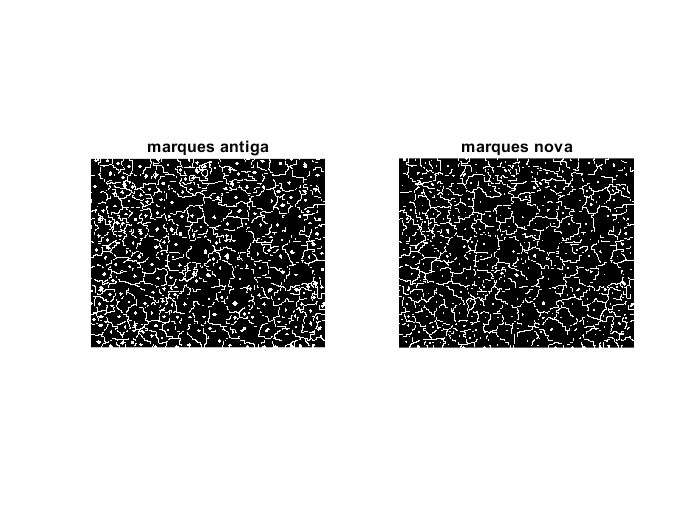

fons2 = fons == 0;
markers2 = fons2|rm4;
figure, subplot(1,2,1), imshow(markers),title('marques antiga');
subplot(1,2,2), imshow(markers2),title('marques nova');

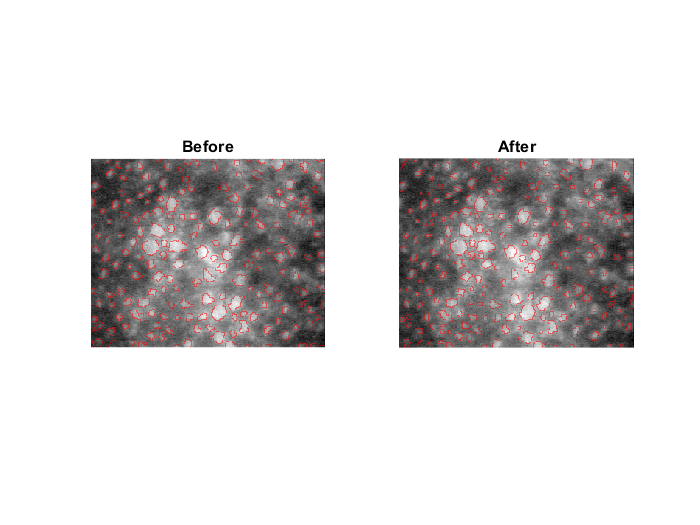

segm=watershed(imimposemin(grad,markers2));
labels = imdilate(segm==0,ones(1));
C = [1, 0, 0];
imSeg2 = labeloverlay(orig, labels, 'Colormap', C);
figure; subplot(1,2,1); imshow(imSeg); title('Before');
subplot(1,2,2); imshow(imSeg2); title('After');

## 2. Segmentació per clustering. K-means

(completeu allò que es demana, i el que creieu que falta) Obriu la imatge 'cornea.tif'

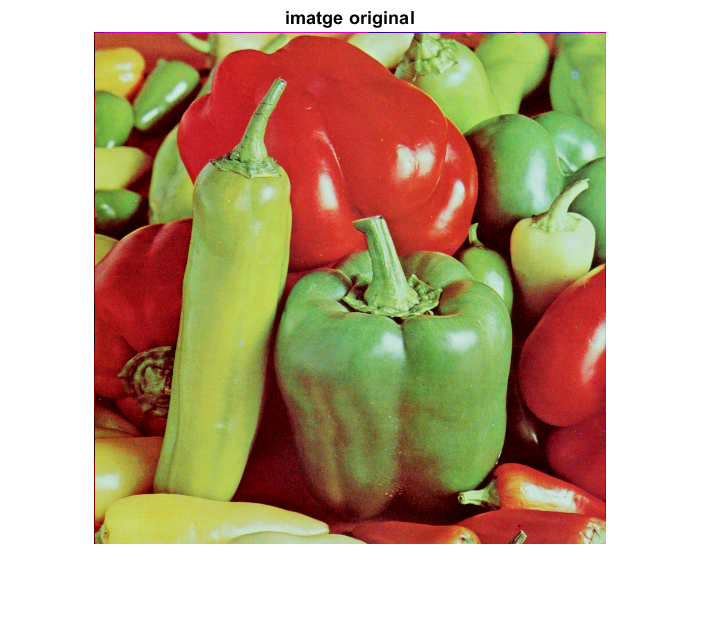

im = imread('peppers.png');
[MAXFILA MAXCOL chan]=size(im);
figure,imshow(im),title('imatge original');

% la segmentarem per color. Treballarem en l’espai Hue-Sat
hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);
vect=reshape(hs,MAXFILA*MAXCOL,2); % feature vector. 2 features per píxel
Nclusters=3; %vermell, verd, i negre
% Usarem la funció kmeans amb distancia citiblock
[cluster_idx, cluster_center] = kmeans(vect,Nclusters,'distance','cityblock');

Consulteu al help els paràmetres de la funció kmeans 

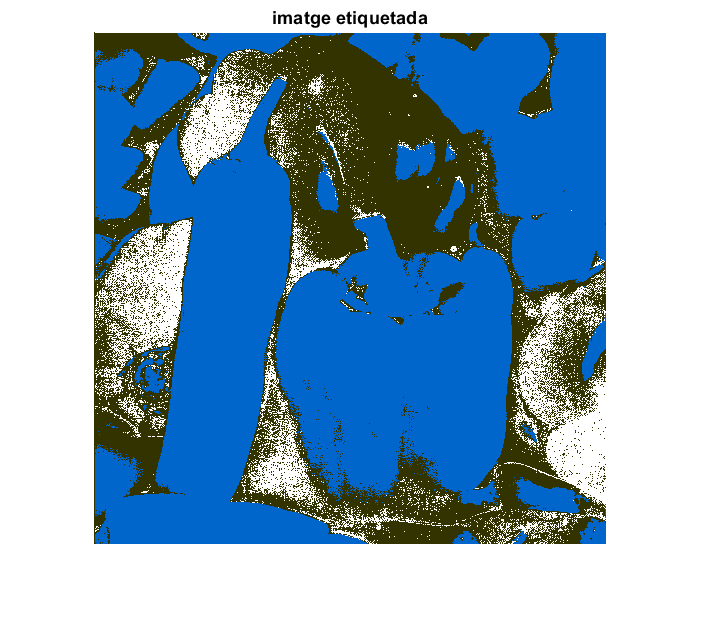

% obtenim la imatge etiquetada pel número cluster
eti=reshape(cluster_idx,MAXFILA,MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

%Algo no va. Els pebrots vermells queden mal segmentats. (COMTE! EL RESULTAT DE
%KMEANS ÉS SEMPRE DIFERENT. DEPÈN DE L%EXECUCIÓ, EL RESULTAT PODRIA
%SORTIT MILLOR O PITJOR)


Què està passant ? 

Els pebrots de color vermell no els identifica bé, deixant apart els punts on hi ha una taca per l'efecte de l'iluminació, l'algorisme separa en clusters diferents colors molt semblants de vermell. 

Com es comenta més avall, la raó es degut al Hue que és cíclic, llavors colors molt semblants pot apareixer molt distants, i finalment kmeans el separa en clusters diferents.

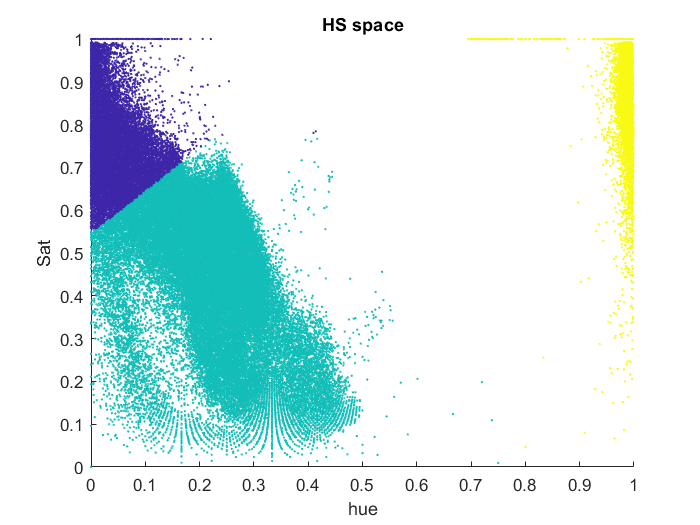

% Representem els píxels en l’espai hue-sat
figure,scatter(vect(:,1),vect(:,2),1,cluster_idx);
xlabel('hue');ylabel('Sat')
title('HS space')

% El hue és un angle. És cíclic.
% Píxels vermells amb hue molt similars queden a banda i banda de l’espai hue-sat per culpa del
% pas per zero.

## Exercici

la funció kmeans implementada a matlab no funciona amb aritmètica cíclica, per tant, les característiques no poden ser angles. Implementeu vosaltres una funció kmeans que pugui treballar amb característiques cícliques.

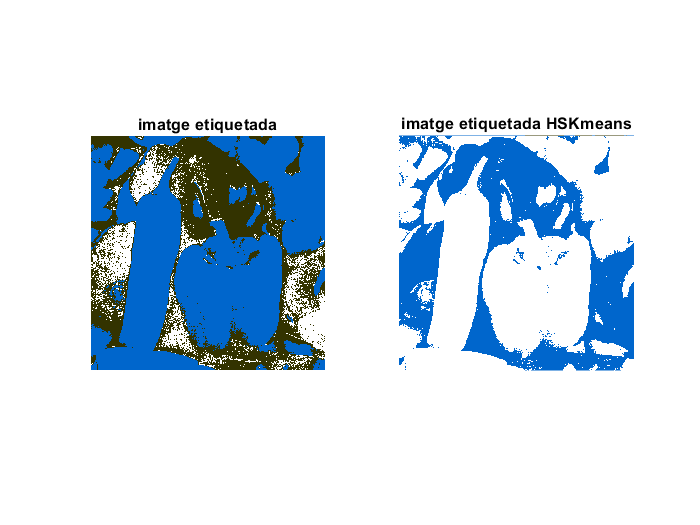

tol = 1; maxIter = 20;
[means, cluster_size, cluster_idx] = HSKmeans(vect, Nclusters, tol, maxIter);
eti2=reshape(cluster_idx,MAXFILA,MAXCOL);
figure, subplot(1,2,1), imshow(eti,[]),colormap(colorcube), title('imatge etiquetada');
subplot(1,2,2), imshow(eti2,[]),colormap(colorcube), title('imatge etiquetada HSKmeans');

funció kmeans extraida de: 

[https://www.mathworks.com/matlabcentral/fileexchange/16762-k-means-algorithm-demo](https://www.mathworks.com/matlabcentral/fileexchange/16762-k-means-algorithm-demo)

modificada per adaptar a l'espai HS, i a la métrica Cityblock com l'enunciat

function [means,Nmeans,membership] = HSKmeans(X, K, maxerr, maxiter)
    % Per defecte usa la distancia cityblock,
    [Ndata, dims] = size(X);
    dist = zeros(1,K);
    means = zeros(K,dims);
    if (nargout > 2)
        membership = zeros(Ndata,1);
    end
    % Initial prototype assignment (arbitrary)
    for i=1:K-1
       means(i,:) = X(i,:);
    end
    means(K,:) = mean(X(K:Ndata,:));
    cmp = 1 + maxerr;
    iter = 1;
    while (cmp > maxerr && iter <= maxiter)
       iter = iter+1;
       % Sums (class) and data counters (Nclass) initialization
       class = zeros(K,dims);
       Nclass = zeros(K,1);
       % Groups each elements to the nearest prototype
       for i=1:Ndata
          for j=1:K
             % Euclidean distance from data to each prototype
             %dist(j) = norm(X(i,:)-means(j,:))^2;
             dist(j) = HSCityblock(X(i,:),means(j,:));
          end
          % Find indices of minimum distance
          index_min = find(~(dist-min(dist)));
          % If there are multiple min distances, decide randomly
          index_min = index_min(ceil(length(index_min)*rand));
          if (nargout > 2)
              membership(i) = index_min;
          end
          class(index_min,:) = class(index_min,:) + X(i,:);
          Nclass(index_min) = Nclass(index_min) + 1;
       end
       for i=1:K
          class(i,:) = class(i,:) / Nclass(i);
       end
       % Compare results with previous iteration
       cmp = 0;
       for i=1:K
          cmp = cmp + HSCityblock(class(i,:),means(i,:)); 
       end
       % Prototype update
       means = class;
    end
    Nmeans = Nclass;

end

% distancia cityblock amb Hue i Saturation com features. Elaboració propia
function d = HSCityblock(A, B)
    h1 = A(1,1);
    h2 = B(1,1);
    s1 = A(1,2);
    s2 = B(1,2);
    dh = min(abs(h1-h2), 1-abs(h1-h2));
    ds = abs(s1-s2);
    d = dh+ds;
end